correlation signals

p = pi

p = 3.1416

tau_s = 100;
f_s = 1/tau_s;
x = [1:tau_s];

x_s = cos( 2*p*f_s*x)

x_s =     0.9980    0.9921    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628   -0.0000   -0.0628   -0.1253   -0.1874   -0.2487   -0.3090   -0.3681   -0.4258   -0.4818   -0.5358   -0.5878   -0.6374   -0.6845   -0.7290   -0.7705   -0.8090   -0.8443   -0.8763   -0.9048   -0.9298   -0.9511   -0.9686   -0.9823   -0.9921   -0.9980   -1.0000


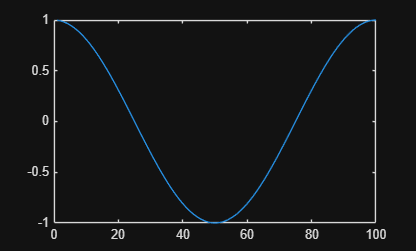

plot(x, x_s)

now for symbols that divide tau_s, each of tau_s total length

% each divide tau_s, which is th number of indices for each symbol
tau_0 = 20;
tau_1 = 5;
f_0 = 1/tau_0;
f_1 =  1/ tau_1;


x_0 = cos( 2*p*f_0*x)

x_0 =     0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000


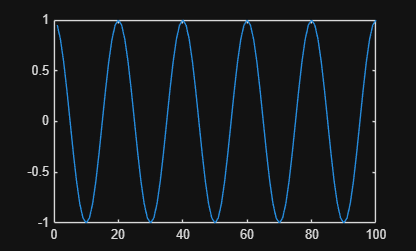

plot(x, x_0)

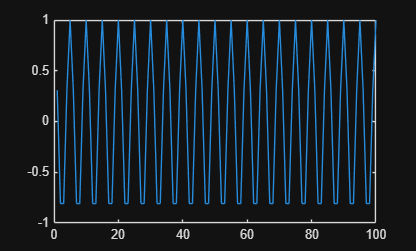

x_1 = cos(2*p*f_1*x);
plot(x, x_1)

assuming perfect integer values of tau_s

assert(mod(tau_s/ tau_0, 2) == 0)
assert(mod(tau_s/ tau_1, 2) == 0)

compute the scalar product with received signal r

% raw correlations
z0 = [];
z1 = [];


% total number of loop iterations (i = 5.89 -> i = 5)
iterations = floor( r.length() / tau_s );

for n = [0:1:iterations]

    t0 = (n - 1) * tau_s + 1;
    t1 = n * tau_s;
    
    % elementwise multiplication and summation
    z0_n = sum(  r(t0:t1) * x_0 );
    z0 = [z0, z0_n];
    
    z1_n = sum (    r(t0:t1) * x_1 );
    z1 = [z1, z1_n];

end

difference between raw correlations

% compute difference z1 - z0
z_diff = z1-z0;

dec_bits = double(z_diff > 0);